
clear all
close all

% Defining initial conditions and timespan for the ODE solver
x0 = [1 1];
TimeSpan = [0 20]; % The timespan should be small, for example [0 1].


%matrix
A = [-1 2;
     -2 -3];    
eig(A)    

ans =   -2.0000 + 1.7321i
  -2.0000 - 1.7321i


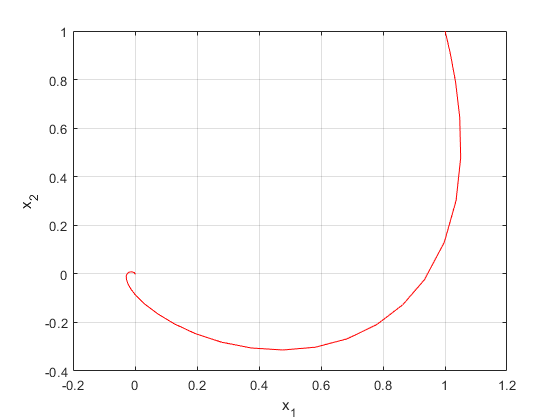

dx = @(x,t) A*x*t; %function
    
% Solving the ode over the specified time domain
options = odeset('RelTol',1e-3,'AbsTol',1e-3);
[T X] = ode45(dx,TimeSpan,x0,options);



% Plotting the results
figure
plot(X(:,1),X(:,2),'r-')
grid on
xlabel('x_1')
ylabel('x_2')

Q = eye(2)

Q =      1     0
     0     1


L = lyap(A,Q)

L =     0.3571   -0.0714
   -0.0714    0.2143


eig(L)

ans =     0.1847
    0.3867
